SpellLevel = 1:9;
SpellMod = 6;
MAXAC = 30;
AverageDamage = zeros(MAXAC,9);
iterations = 10000;

for h = 1:MAXAC
    for i = SpellLevel
        for j = 1:iterations
            SavedDamage = 0;
            for k = 1:i+1 %Multi target
                r = randi(20)+SpellMod;
                Freq = zeros(1,8);
                if(r-SpellMod == 20)
                    DamageRolls = zeros(1,(i+2)*2);
                    for l = 1:(i+2)*2
                        r = randi(8);
                        Freq(r) = Freq(r) + 1;
                        DamageRolls(l) = r;
                    end
                else
                    DamageRolls = zeros(1,i+2);
                    if(r >= h)
                        for l = 1:i+2
                            r = randi(8);
                            Freq(r) = Freq(r) + 1;
                            DamageRolls(l) = r;
                        end
                    end
                end
                if(max(Freq) == 1 || k == i+1)

                    if(j == 0) 
                        AverageDamage(h,i) = sum(DamageRolls)+SavedDamage;
                    else
                        AverageDamage(h,i) = (j*AverageDamage(h,i)+sum(DamageRolls)+SavedDamage)/(j+1);  %return (size * average + value) / (size + 1);
                    end
                    break
                else
                    SavedDamage = SavedDamage+sum(DamageRolls);
                end
            end
        end
    end
end



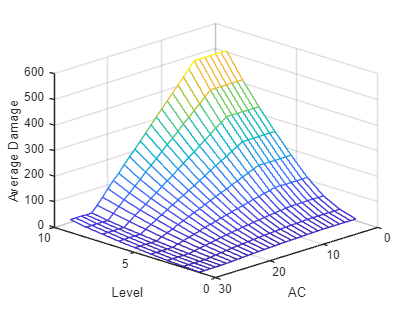

mesh(AverageDamage)

view([-135 25])
xlabel("Level")
ylabel("AC")
zlabel("Average Damage")